# WARNING: BENCHMARKING IN MATLAB LIVE SCRIPTS IS BAD PRACTICE. 

## CONSIDER THIS MORE OF A "PROOF OF CONCEPT" THAN AN ACTUAL REPRESENTATION OF THE QUALITY OF THESE MODELS

# FOR ACCURATE BENCHMARKS, SEE benchmark.m

% Benchmark Testing

% == DEFAULT VARIABLES ==========================================

% I hate warnings 
warning off; 

% Create a DEM of some size 
sizeDEM = 50;
ZI = peaks(sizeDEM);

% myTIN:
point_tol = 0.2; 

% myPovTIN:
player_coord = [10, 10, 0];
FOV = 25;

% == STANDARD DEM ===============================================


% DEM Figure
figure(1); clf; 
disp('DEM Model:')

DEM Model:


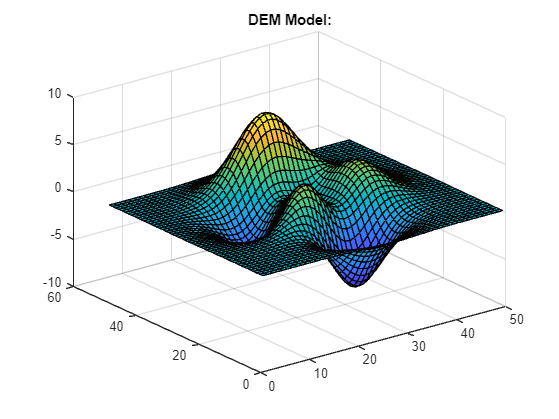

tic; 
surf(ZI);
time = toc; 
title('DEM Model:');

disp(['STANDARD DEM: ', num2str(time)]);

STANDARD DEM: 0.020166


disp('-----');

-----


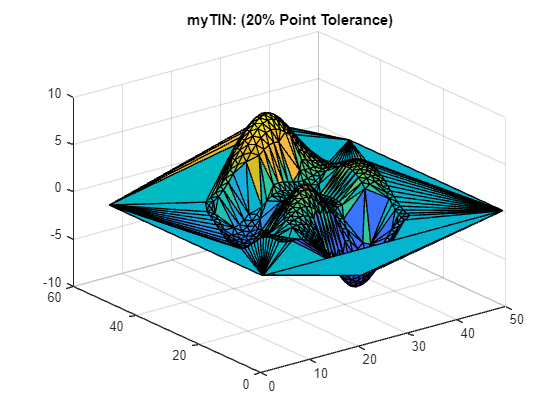



% == myTIN ======================================================

% Create Figure
figure(2); clf; 

% Find TIN model from DEM shown above
[tri, x, y, z] = myTIN(ZI, point_tol);

% Plot the TIN found 
tic;
trisurf(tri, x, y, z);
time = toc;

% Update Figure and Separate
title(['myTIN: (', num2str(100*point_tol), '% Point Tolerance)']);

disp(['myTIN   : ', num2str(time)]);

myTIN   : 0.02023


disp('-----');

-----


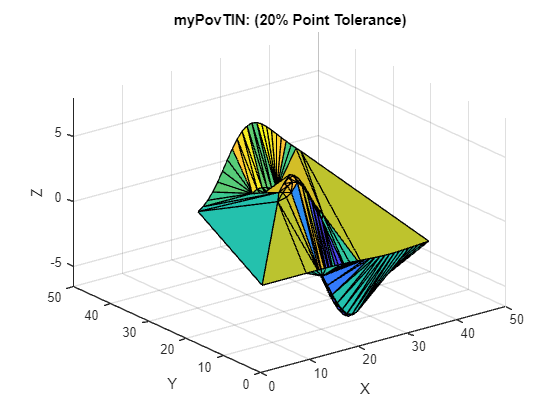



% == myPovTIN ===================================================

% Use MyPovTIN!
[tri, x, y, z] = myPovTIN(player_coord, FOV, ZI, point_tol);

% Plot the surface using trisurf
figure(3); clf;
tic;
trisurf(tri, x, y, z);
time = toc; 

% Set axis limits (do not change xlim, ylim, or zlim)
xlim([0, sizeDEM]);
ylim([0, sizeDEM]);
zlim([min(ZI(:)), max(ZI(:))]);

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title(['myPovTIN: (', num2str(100*point_tol), '% Point Tolerance)']);

disp(['myPovTIN: ', num2str(time)]);

myPovTIN: 0.010162


disp('-----');

-----
